# Execution 

- Problem 4: Executing the algorithm made in the previous problem for 4 types of aircrafts: general aviation-single engine, general aviation-twin engine, jet transport, and military cargo.

- (Assumption) No loitering 

The aircrafts are listed below

General Aviation-Single Engine

- Cessna TTX: Range 1250 nmi, payload 578 lb, 0.312 Mach, piston-prop fixed pitch

- Cirrus Vision SF50: 796 nmi, payload 1328 lb, 0.45 Mach, high-bypass turbofan

- Valcanair V1.0: 575 nmi, payload 970 lb,  0.192 Mach, piston-prop fixed pitch

General Aviation-Twin Engine

- Piper Seneca: 828 nmi, payload 1331 lb, 0.300 Mach, piston-prop fixed pitch

- Beechcraft B55 Baron: 933 nmi, payload 900 lb, 0.300 Mach, piston-prop fixed pitch

- Honda Jet HA-420: 1223 nmi, payload 547 lb, 0.633 Mach, high-bypass turbofan

Jet Transport 

- Boeing 737-900: Range 2950 nmi, payload 44622 lb, 0.79 Mach, high-bypass turbofan

- Boeing 787-8: Range 7355 nmi, 90500 lb, 0.90 Mach, high-bypass turbofan

- Airbus A380: Range 8000 nmi, 185000 lb, 0.89 Mach, high-bypass turbofan

Military Cargo

- Kawasaki C-1: Range 1810 nmi, payload 34128 lb, 0.53 Mach, high-bypass turbofan

- Boeing C-17 Globemaster 3: Range 2420 nmi, 170900 lb, 0.74 Mach, high-bypass turbofan

- Lockheed C-5 Galaxy: Range 5500 nmi, payload 285000 lb, 0.79 Mach, high-bypass turbofan

Now, callout function created in problem three for each of the aircrafts above. Entering each specification as the inputs.

%Cessna TTX
[W_gross1, T1, Wempty_W01, W0_new1, We_W0_final1] = takeoff_weight_sizing(578, 0, 1250, 0.312, "piston-prop fixed pitch", "english",...
    "general aviation single engine", 11, 0, 0);

W3_W2 = 0.8193

Wf_W0 = 0.3835

T = 19×4 table
    W0_guess    Wempty_W0     Wempty      W0_new
    ________    _________    _________    ______

      1e+18     0.001358     1.358e+15    2240.2
     2240.2      0.58865        1318.7     49525
      49525      0.33717         16698    4933.5
     4933.5      0.51067        2519.4     13024
      13024       0.4288        5584.7    7342.5
     7342.5       0.4754        3490.6    9767.7
     9767.7       0.4516        4411.1    8357.4
     8357.4      0.46445        3881.6    9064.1
     9064.1      0.45771        4148.8    8679.5
     8679.5       0.4613        4003.9    8880.1
     8880.1      0.45941        4079.6    8773.1
     8773.1      0.46041        4039.2    8829.5
     8829.5      0.45988        4060.5    8799.5
     8799.5      0.46016        4049.2    8815.4
     8815.4      0.46001        4055.2      8807
       8807    

%Cirrus Vision SF50
[W_gross2, T2, Wempty_W02, W0_new2, We_W0_final2] = takeoff_weight_sizing(1328, 0, 796, 0.45, "high-bypass turbofan", "english",...
    "general aviation single engine", 12, 0, 0);

W3_W2 = 0.8655

Wf_W0 = 0.3051

T = 12×4 table
    W0_guess    Wempty_W0     Wempty      W0_new
    ________    _________    _________    ______

      1e+18     0.001358     1.358e+15    3068.1
     3068.1      0.55626        1706.7     15344
      15344      0.41634        6388.2      7638
       7638      0.47204        3605.4    9546.6
     9546.6      0.45346          4329    8812.2
     8812.2      0.46004          4054    9059.1
     9059.1      0.45776        4146.9    8971.9
     8971.9      0.45856        4114.1    9002.2
     9002.2      0.45828        4125.5    8991.6
     8991.6      0.45838        4121.5    8995.3
     8995.3      0.45834        4122.9      8994
       8994      0.45835        4122.4    8994.4


%Valcanair V1.0
[W_gross3, T3, Wempty_W03, W0_new3, We_W0_final3] = takeoff_weight_sizing(970, 0, 575, 0.192, "piston-prop fixed pitch", "english",...
    "general aviation single engine", 10.5, 0, 0);

W3_W2 = 0.9084

Wf_W0 = 0.2284

T = 11×4 table
    W0_guess    Wempty_W0     Wempty      W0_new
    ________    _________    _________    ______

      1e+18     0.001358     1.358e+15    2297.9
     2297.9      0.58597        1346.5    9533.6
     9533.6      0.45357        4324.2    5565.1
     5565.1      0.49972          2781    6509.6
     6509.6      0.48582        3162.5      6193
       6193       0.4902        3035.8    6289.4
     6289.4      0.48884        3074.5    6259.1
     6259.1      0.48926        3062.3    6268.5
     6268.5      0.48913        3066.1    6265.6
     6265.6      0.48917        3064.9    6266.5
     6266.5      0.48916        3065.3    6266.2


%Piper Seneca 
[W_gross4, T4, Wempty_W04, W0_new4, We_W0_final4] = takeoff_weight_sizing(828, 0, 828, 0.300, "piston-prop fixed pitch", "english",...
    "general aviation twin engine", 13, 0,0);

W3_W2 = 0.8943

Wf_W0 = 0.2540

T = 14×4 table
    W0_guess    Wempty_W0     Wempty      W0_new
    ________    _________    _________    ______

      1e+18      0.02409     2.409e+16    2255.2
     2255.2       0.7023        1583.8     37273
      37273      0.53052         19774      7556
       7556      0.62232        4702.2     13165
      13165      0.58871        7750.4     10351
      10351      0.60304        6242.3     11389
      11389       0.5973        6802.7     10950
      10950      0.59966        6566.1     11126
      11126       0.5987        6661.1     11054
      11054      0.59909        6622.2     11083
      11083      0.59893          6638     11071
      11071        0.599        6631.6     11076
      11076      0.59897        6634.2     11074
      11074      0.59898        6633.1     11075


%Beechcraft B55 Baron 
[W_gross5, T5, Wempty_W05, W0_new5, We_W0_final5] = takeoff_weight_sizing(900, 0, 933, 0.300, "piston-prop fixed pitch", "english",...
    "general aviation twin engine", 13, 0,0);

W3_W2 = 0.8817

Wf_W0 = 0.2765

T = 16×4 table
    W0_guess    Wempty_W0     Wempty      W0_new
    ________    _________    _________    ______

      1e+18      0.02409     2.409e+16    2430.7
     2430.7      0.69706        1694.4     64367
      64367      0.50232         32332    7686.9
     7686.9      0.62125        4775.5     16631
      16631      0.57511        9564.7     11459
      11459      0.59694        6840.1     13435
      13435      0.58751        7893.5     12504
      12504      0.59175        7399.2     12906
      12906      0.58988        7613.1     12725
      12725      0.59071        7517.1     12805
      12805      0.59034        7559.5     12770
      12770      0.59051        7540.6     12785
      12785      0.59043          7549     12778
      12778      0.59047        7545.3     12782
      12782      0.59045        7546.9     12780
      12780    

%Honda Jet HA-420
[W_gross6, T6, Wempty_W06, W0_new6, We_W0_final6] = takeoff_weight_sizing(547, 0, 1223, 0.633, "high-bypass turbofan", "english", ...
    "general aviation twin engine", 15, 0, 0);

W3_W2 = 0.8815

Wf_W0 = 0.2770

T = 18×4 table
     W0_guess     Wempty_W0     Wempty        W0_new  
    __________    _________    _________    __________

         1e+18     0.02409     2.409e+16        1927.4
        1927.4     0.71342          1375    1.4114e+05
    1.4114e+05     0.46439         65543        5209.2
        5209.2      0.6459        3364.6         17479
         17479     0.57226         10002        8937.8
        8937.8     0.61196        5469.6         12134
         12134     0.59353        7201.9         10407
         10407     0.60272        6272.3         11202
         11202      0.5983        6701.8         10804
         10804     0.60046        6487.6         10995
         10995     0.59941        6590.7         10902
         10902     0.59992        6540.2         10947
         10947     0.59967        6564.7         10925
         10925     0.59

%Boeing 737-900
[W_gross7, T7, Wempty_W07, W0_new7, We_W0_final7] = takeoff_weight_sizing(44622, 0, 2950, 0.79, "high-bypass turbofan", "english",...
    "jet transport", 17, 0,0);

W3_W2 = 0.8064

Wf_W0 = 0.4047

T = 10×4 table
     W0_guess     Wempty_W0      Wempty        W0_new  
    __________    _________    __________    __________

         1e+18    0.088234     8.8234e+16         89578
         89578     0.53518          47940    7.5554e+05
    7.5554e+05     0.47091     3.5579e+05    3.6516e+05
    3.6516e+05     0.49191     1.7962e+05    4.3932e+05
    4.3932e+05     0.48648     2.1372e+05    4.1741e+05
    4.1741e+05     0.48798     2.0369e+05    4.2323e+05
    4.2323e+05     0.48757     2.0635e+05    4.2163e+05
    4.2163e+05     0.48768     2.0562e+05    4.2207e+05
    4.2207e+05     0.48765     2.0582e+05    4.2195e+05
    4.2195e+05     0.48766     2.0577e+05    4.2198e+05


%These two aircrafts have too high range that the algorithm returns error
%So I will use values on the internet 
%Boeing 787-8
% [W_gross8, T8, Wempty_W08, W0_new8, We_W0_final8] = takeoff_weight_sizing(90500, 0, 7355, 0.90, "high-bypass turbofan", "english",...
%     "jet transport", 18, 0,0);
W_gross8 = 502,500;

W_gross8 = 502

We_W0_final8 = 0.5264;
% %Airbus A380
% [W_gross9, T9, Wempty_W09, W0_new9, We_W0_final9] = takeoff_weight_sizing(185000, 0, 8000, 0.89, "high-bypass turbofan", "english",...
%     "jet transport", 18.5, 0, 0);
W_gross9 = 1234600;
We_W0_final9 = 0.4947;

%Kawasaki C-1
[W_gross10, T10, Wempty_W010, W0_new10, We_W0_final10] = takeoff_weight_sizing(34128, 0, 1810, 0.53, "high-bypass turbofan", "english",...
    "military cargo", 16,0,0);

W3_W2 = 0.8113

Wf_W0 = 0.3967

T = 7×4 table
     W0_guess     Wempty_W0      Wempty        W0_new  
    __________    _________    __________    __________

         1e+18    0.051107     5.1107e+16         63250
         63250     0.42895          27131     2.003e+05
     2.003e+05      0.3957          79260    1.6822e+05
    1.6822e+05     0.40056          67384    1.7226e+05
    1.7226e+05      0.3999          68886     1.717e+05
     1.717e+05     0.39999          68677    1.7177e+05
    1.7177e+05     0.39998          68706    1.7176e+05


%Boeing C-17
[W_gross11, T11, Wempty_W011, W0_new11, We_W0_final11] = takeoff_weight_sizing(170900, 0, 2420, 0.74, "high-bypass turbofan", "english",...
    "military cargo", 18, 0,0);

W3_W2 = 0.8370

Wf_W0 = 0.3541

T = 6×4 table
     W0_guess     Wempty_W0      Wempty        W0_new  
    __________    _________    __________    __________

         1e+18    0.051107     5.1107e+16    2.8866e+05
    2.8866e+05     0.38571     1.1134e+05    6.5985e+05
    6.5985e+05     0.36402      2.402e+05    6.0909e+05
    6.0909e+05     0.36606     2.2296e+05    6.1354e+05
    6.1354e+05     0.36588     2.2448e+05    6.1313e+05
    6.1313e+05     0.36589     2.2434e+05    6.1317e+05


%Lockheed C-5
[W_gross12, T12, Wempty_W012, W0_new12, We_W0_final12] = takeoff_weight_sizing(285000, 0, 5500, 0.79, "high-bypass turbofan", "english",...
    "military cargo", 18, 0, 0);

W3_W2 = 0.6846

Wf_W0 = 0.5877

T = 10×4 table
     W0_guess     Wempty_W0      Wempty        W0_new  
    __________    _________    __________    __________

         1e+18    0.051107     5.1107e+16     7.912e+05
     7.912e+05     0.35942     2.8437e+05    5.4018e+06
    5.4018e+06      0.3142     1.6972e+06    2.9125e+06
    2.9125e+06     0.32808     9.5554e+05    3.3925e+06
    3.3925e+06      0.3246     1.1012e+06    3.2577e+06
    3.2577e+06     0.32552     1.0605e+06    3.2923e+06
    3.2923e+06     0.32528     1.0709e+06    3.2832e+06
    3.2832e+06     0.32534     1.0682e+06    3.2856e+06
    3.2856e+06     0.32533     1.0689e+06     3.285e+06
     3.285e+06     0.32533     1.0687e+06    3.2851e+06


Polyfit the best-fit line for each type of aircraft as W0_new# on x-axis and We_W0_final# as y-axis

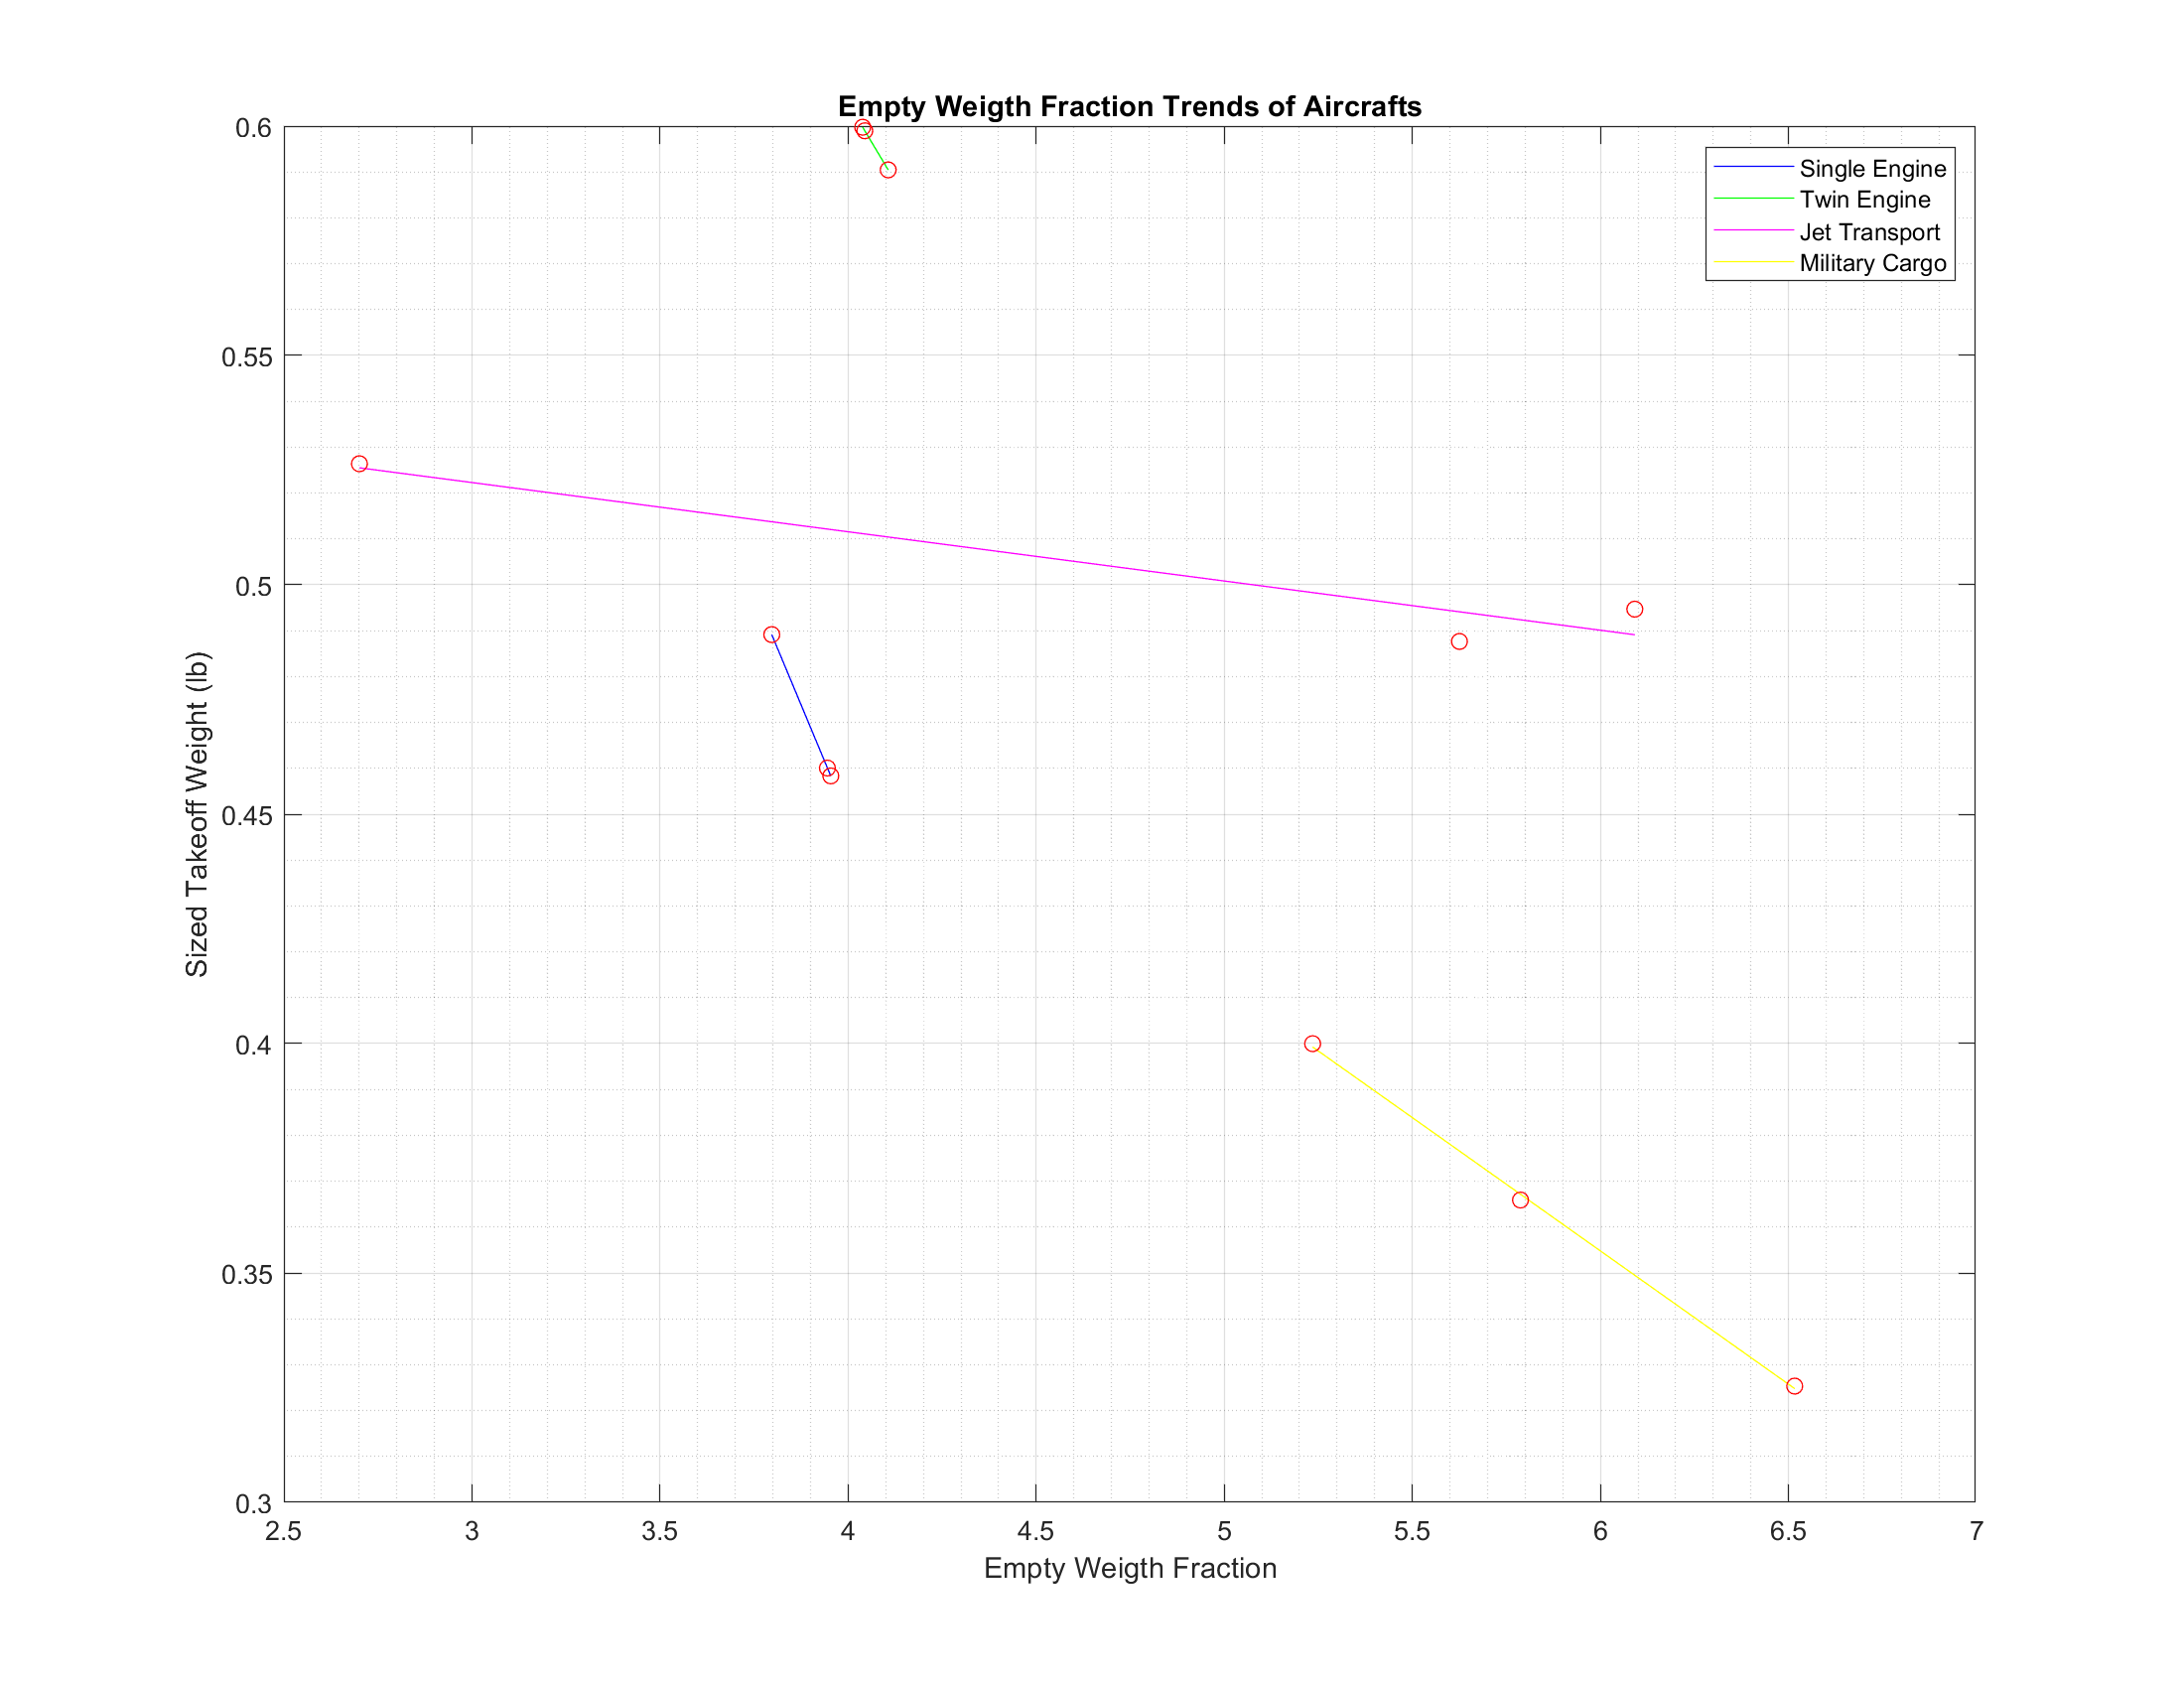

%First create vector from the given data to plot
%Single Engine
W0_singEng = [W_gross1 W_gross2 W_gross3]; %x-values
WeFrac_singEng = [We_W0_final1 We_W0_final2 We_W0_final3]; %y-values

%Twin Engines
W0_twinEng = [W_gross4 W_gross5 W_gross6]; 
WeFrac_twinEng = [We_W0_final4 We_W0_final5 We_W0_final6];

%Jet Transport
W0_JT = [W_gross7 W_gross8 W_gross9];
WeFrac_JT = [We_W0_final7 We_W0_final8 We_W0_final9];

%Military Cargo
W0_MC = [W_gross10 W_gross11 W_gross12];
WeFrac_MC = [We_W0_final10 We_W0_final11 We_W0_final12];

%Calibrate the data by semilogX which gives a clean linear
%graph (better than normal plot). Take log10 for all x-values.
%Then polyfit each of them
%Single Engine
W0_singEng = log10(W0_singEng);
p1 = polyfit(W0_singEng, WeFrac_singEng, 1);
fit1 = polyval(p1, W0_singEng);

%Twin Engine
W0_twinEng = log10(W0_twinEng);
p2 = polyfit(W0_twinEng, WeFrac_twinEng,1);
fit2 = polyval(p2, W0_twinEng);

%Jet Transport
W0_JT = log10(W0_JT);
p3 = polyfit(W0_JT, WeFrac_JT,1);
fit3 = polyval(p3, W0_JT);

%Military Cargo
W0_MC = log10(W0_MC);
p4 = polyfit(W0_MC, WeFrac_MC,1);
fit4 = polyval(p4, W0_MC);

%Plotting 
figure(1)
plot(W0_singEng, fit1, "-b")
title("Empty Weigth Fraction Trends of Aircrafts")
ylabel("Empty Weigth Fraction")
xlabel("Sized Takeoff Weight (log10(lb))")
grid on
grid minor 
box on
hold on
plot(W0_twinEng, fit2, "-g")
plot(W0_JT, fit3, "-m")
plot(W0_MC, fit4, "-y")
plot(W0_singEng, WeFrac_singEng, "or")
plot(W0_twinEng, WeFrac_twinEng, "or")
plot(W0_JT, WeFrac_JT, "or")
plot(W0_MC, WeFrac_MC, "or")
hold off
legend("Single Engine", "Twin Engine", "Jet Transport", "Military Cargo");
set(gcf,'PaperPositionMode','auto','Position',[0 0 1100 850]) % Control where plots are positioned

## Analysis

- Do the different types of aircraft occupy different parts of your plot, and why/why not? 

ANS: 

Yes, they do. For the jet transport the high values of the range and payload giver larger results for the takeoff weight; but, lower empty weight fractions.

And vice versa for the light single engine and twin engine aircrafts.

- Within a given type of aircraft, does the empty weight fraction vary, and why/why not? 

ANS:

Yes, they vary. As stated above the takeoff weight is dependent of the payload and the range, and within a category of aircrafts there are aircrafts with different payloads and ranges even though the flight mission might be alike. With such change of parameters, the empty weight fraction can vary. Such trend can be observed in the graph above for all aircraft categories. 

- Are your results similar to Raymer’s table, and why/why not?

ANS: 

Yes, my graph and the graph on Raymer is somewhat alike. For example, the general aviation-twin engine category range in the empty weight fraction of around 6 with a negative slope. This is the very close to the example in Raymer. Jet transport and military cargo appear at the right hand side and low empty weight ratio (where military cargo ranges lower than jet transport). These trends are similar which makes it reasonable to conclude that the example graph and my graph are similar to each other.